1.multisphere

Create geometry formed by several spherical cells

[`gm = multisphere(R)`](https://ww2.mathworks.cn/help/pde/ug/multisphere.html#d120e59593)

[`gm = multisphere(R,'Void',eci)`](https://ww2.mathworks.cn/help/pde/ug/multisphere.html#d120e59619)

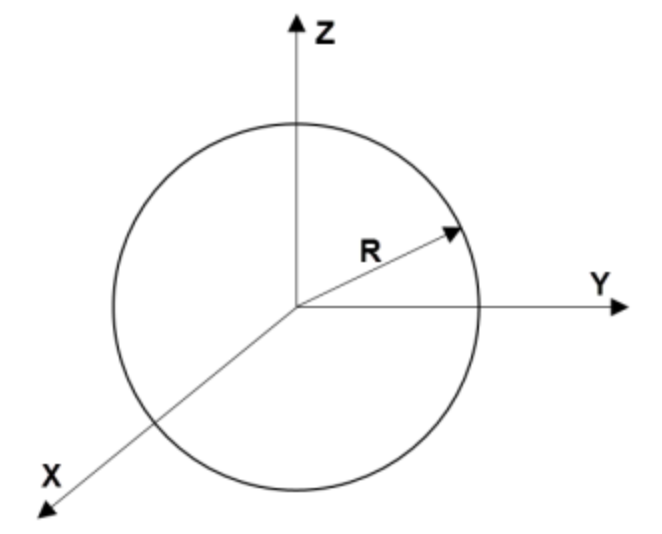

1.1环形球

gm = multisphere([5 10 15])

gm =   DiscreteGeometry - 属性:

       NumCells: 3
       NumFaces: 3
       NumEdges: 0
    NumVertices: 0


model = createpde

model =   PDEModel - 属性:

           PDESystemSize: 1
         IsTimeDependent: 0
                Geometry: []
    EquationCoefficients: []
      BoundaryConditions: []
       InitialConditions: []
                    Mesh: []
           SolverOptions: [1×1 PDESolverOptions]


model.Geometry = gm

model =   PDEModel - 属性:

           PDESystemSize: 1
         IsTimeDependent: 0
                Geometry: [1×1 DiscreteGeometry]
    EquationCoefficients: []
      BoundaryConditions: []
       InitialConditions: []
                    Mesh: []
           SolverOptions: [1×1 PDESolverOptions]


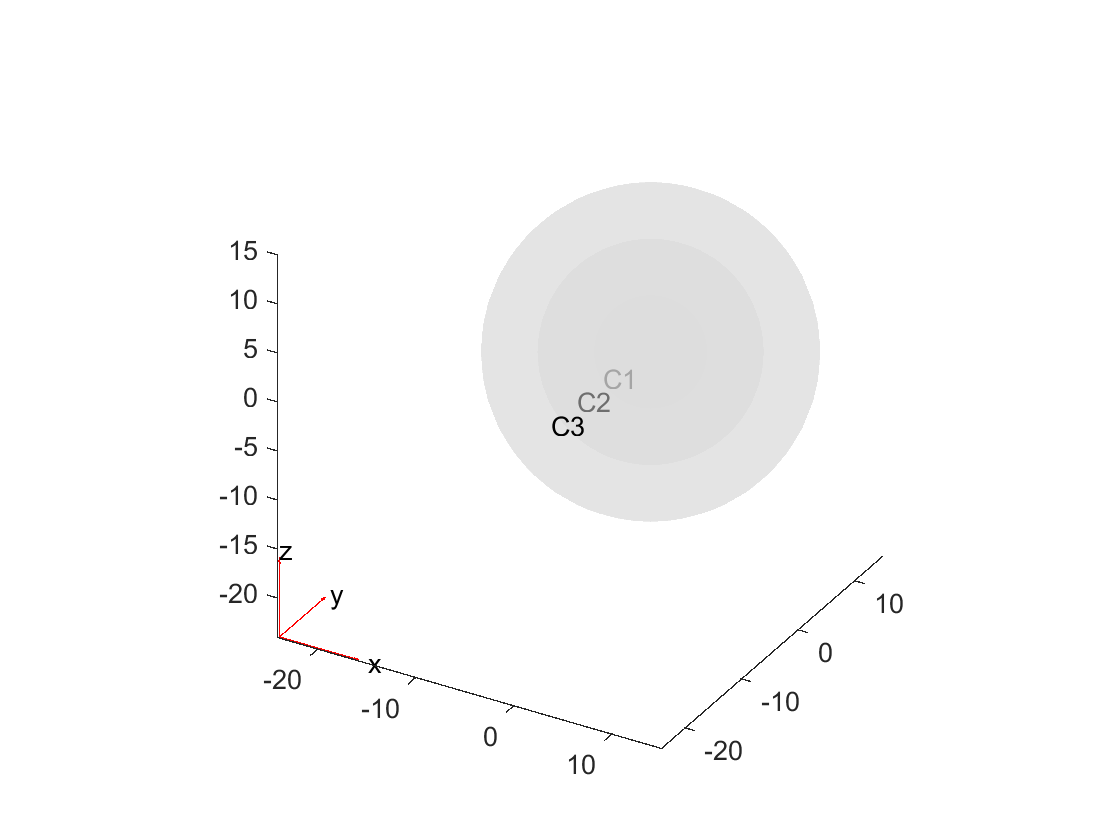

pdegplot(model,'CellLabels','on','FaceAlpha',0.5)

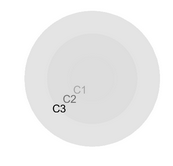

1.2空洞球

gm = multisphere([9 10],'Void',[true,false])

gm =   DiscreteGeometry - 属性:

       NumCells: 1
       NumFaces: 2
       NumEdges: 0
    NumVertices: 0


model = createpde

model =   PDEModel - 属性:

           PDESystemSize: 1
         IsTimeDependent: 0
                Geometry: []
    EquationCoefficients: []
      BoundaryConditions: []
       InitialConditions: []
                    Mesh: []
           SolverOptions: [1×1 PDESolverOptions]


model.Geometry = gm

model =   PDEModel - 属性:

           PDESystemSize: 1
         IsTimeDependent: 0
                Geometry: [1×1 DiscreteGeometry]
    EquationCoefficients: []
      BoundaryConditions: []
       InitialConditions: []
                    Mesh: []
           SolverOptions: [1×1 PDESolverOptions]


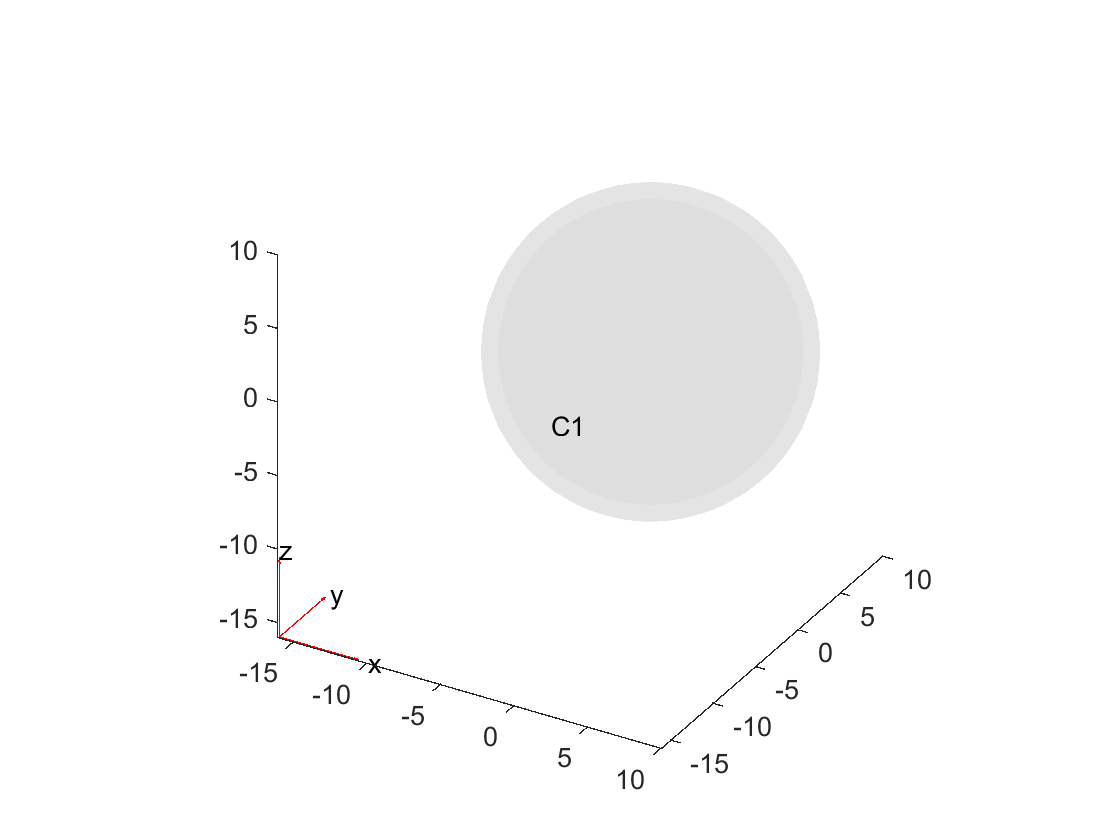

pdegplot(model,'CellLabels','on','FaceAlpha',0.5)